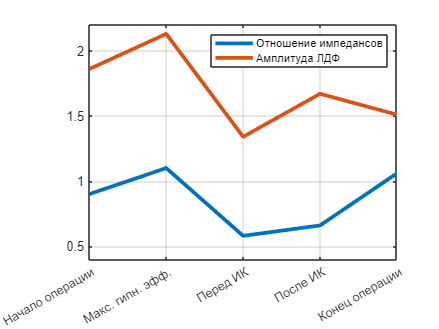

clear all
means_dRR = [0.9,1.1,0.58,0.66,1.06];
means_ldf = [1.86,2.13,1.34, 1.67,1.51];
x=[1,2,3,4,5];
ticklbls = {'Начало операции' 'Макс. гипн. эфф.' 'Перед ИК' 'После ИК' 'Конец операции'};
plot(x,means_dRR,x,means_ldf,"LineWidth",3)
grid on
legend(["Отношение импедансов","Амплитуда ЛДФ"]);
xticks(x);
xticklabels(ticklbls);

% Построение типовых форм для статьи
clear all
NAME = '2025-04-11';
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);
load(strcat('OUT/',NAME,'/CYCLE_DATA.mat'));
load(strcat('OUT/',NAME,'/DATA_LDF.mat'));

nstarts = zeros(1,6);
nstops = zeros(1,6);
N = length(TT.DATE);
for i = 1:N
    if (i ~= 4)
        if i == N
            for j = 1:length(CYCLE_DATA)

                if (CYCLE_DATA{j}.NAME > TT.DATE(i) && (DATA_LDF.DATE_LDF(1) < CYCLE_DATA{j}.NAME))
                    if (nstarts(i) == 0)
                        nstarts(i) = j;

                    end
                end
            end
            nstops(i) = length(CYCLE_DATA);
        else
            for j = 1:length(CYCLE_DATA)
                if (CYCLE_DATA{j}.NAME < TT.DATE(i+1) && (CYCLE_DATA{j}.NAME > TT.DATE(i)) && (DATA_LDF.DATE_LDF(1) < CYCLE_DATA{j}.NAME)) 
                    if (nstarts(i) == 0)
                        nstarts(i) = j;
                    end
                elseif (CYCLE_DATA{j}.NAME >= TT.DATE(i+1) && (DATA_LDF.DATE_LDF(1) < CYCLE_DATA{j}.NAME))
                    nstops(i) = j;
                    break;
                end
                
            end
            
        end
    end
end

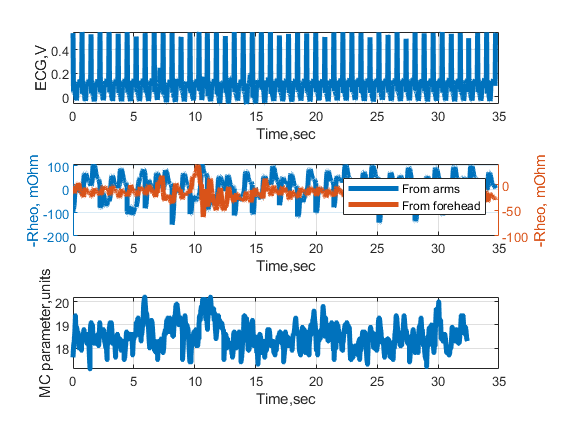

% Построение нескольких циклов вместе
fig = figure();
nstart = nstarts(6)+4;
nend = nstarts(6)+50;
last_time = 0;
last_time_ldf = 0;
data_time = [];
data_ecg = [];
data_rheo1 = [];
data_rheo2= [];


val = DATA_LDF.MC((DATA_LDF.DATE_LDF >= CYCLE_DATA{nstart}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{nstart}.NAME+seconds(max(CYCLE_DATA{nstart}.TIME)))));
times =  DATA_LDF.TIME_LDF((DATA_LDF.DATE_LDF >= CYCLE_DATA{nstart}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{nstart}.NAME+seconds(max(CYCLE_DATA{nstart}.TIME)))));

data_ldf = [];
time_ldf = [];
for i=(nstart):nend
    
    data_time = [data_time;(CYCLE_DATA{i}.TIME+last_time)];
    last_time = max(data_time);
    data_ecg = [data_ecg;CYCLE_DATA{i}.ECG];
    data_rheo1 = [data_rheo1;-CYCLE_DATA{i}.RHEO1];
    data_rheo2 = [data_rheo2;-CYCLE_DATA{i}.RHEO2];
    
    val = DATA_LDF.MC((DATA_LDF.DATE_LDF >= CYCLE_DATA{i}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{i}.NAME+seconds(max(CYCLE_DATA{i}.TIME)))));
    times =  DATA_LDF.TIME_LDF((DATA_LDF.DATE_LDF >= CYCLE_DATA{i}.NAME ) & (DATA_LDF.DATE_LDF <= (CYCLE_DATA{i}.NAME+seconds(max(CYCLE_DATA{i}.TIME)))));

    data_ldf = [data_ldf;val];
    time_ldf = [time_ldf;times-times(1)+last_time_ldf];
    last_time_ldf = max(time_ldf);

end
fontsize(fig, 28, "points");

tiledlayout(3,1);

ax1 = nexttile;
plot(data_time,-(data_ecg-0.15),LineWidth = 3);
xlabel("Time,sec");
ylabel("ECG,V");
grid on

ax2 = nexttile;
yyaxis left;
plot(data_time,data_rheo1,LineWidth = 3);
ylabel("-Rheo, mOhm");
yyaxis right;

plot(data_time,data_rheo2,LineWidth = 3);
xlabel("Time,sec");
ylabel("-Rheo, mOhm");
grid on
legend(["From arms","From forehead"]);

ax3 = nexttile;


plot(time_ldf,data_ldf,LineWidth = 3);
xlabel("Time,sec"); 
ylabel("MC parameter,units");
grid on
linkaxes([ax1 ax2,ax3],'x')% ax3

%xlim([0,10]);